# MCIR Example - Copying a circuit

A circuit is constructed and then copied to another circuit. The copied circuit is altered. The response of each circuit is calculated and plotted together for comparison.

import MCIR.*

% Create the first circuit
CIR1 = Circuit("Original");
CIR1 <= "Vin 1 0 PULSE(0 1 1m)"
CIR1 <= "R1 1 2 10k"
CIR1 <= "C1 2 0 100n IC=0"

% Make a copy of it - note that copy() must be used as it is a handle class.
CIR2 = CIR1.copy;
CIR2.name = "Modified";
CIR2.alter("C1", "47n")

CIR1.list

* Original

VIN 1 0 PULSE(0 1 1m 0 0 0 0 0)
R1 1 2 10k
C1 2 0 100n IC=0


CIR2.list

* Modified

VIN 1 0 PULSE(0 1 1m 0 0 0 0 0)
R1 1 2 10k
C1 2 0 47n IC=0


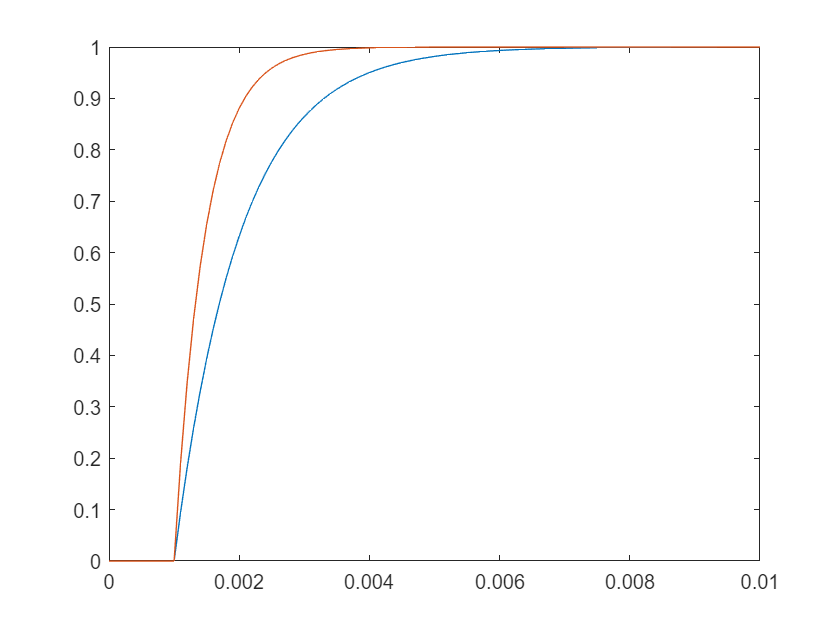

% Simulate and plot for comparison
Trun = "10m";
[y1,t] = CIR1.tr(Trun);
y2 = CIR2.tr(t);

plot(t,y1, t,y2)